clear

## Valores inicales de las variables

Es el ángulo de la articulación del eje xi-1 al eje xi respecto del eje zi-1 (utilizando la regla de la mano derecha)

theta1=0;
theta2=0;
theta3=0;
theta4=0;
theta5=0;
theta6=0;

Vectores de trayectoria de articulaciones

H_A01 = zeros(4,4,0);H_A02 = zeros(4,4,0);H_A03 =zeros(4,4,0);
H_A04 = zeros(4,4,0);H_A05 = zeros(4,4,0);H_A06 =zeros(4,4,0);

for i = 1:20
    clf

view([14.1 23.3])
    axis equal;
    hold on;
    grid;
    view(30,30);

Tensores de las articulaciones

    P0= eye(4);
    A01=Transformacion_avance(theta1,-90,0,0.29);
    A01=P0*A01;
    A12=Transformacion_avance(theta2,0,0.27,0);
    A02=A01*A12;
    A23=Transformacion_avance(theta3,90,-0.07,0);
    A03=A01*A12*A23;
    A34=Transformacion_avance(theta4,-90,0,0.302);
    A04=A01*A12*A23*A34;
    A45=Transformacion_avance(theta5,90,0,0);
    A05=A01*A12*A23*A34*A45;
    A56=Transformacion_avance(theta6,0,0,0.072);
    A06=A01*A12*A23*A34*A56;
  

Plot del robot y sus articulaciones

    plotTensor(P0,"0");
    Connect_axis(P0,A01);
    plotTensor(A01,"1");
    Connect_axis(A01,A02);
    plotTensor(A02,"2");
    Connect_axis(A02,A03);
    plotTensor(A03,"3");
    Connect_axis(A03,A04);
    plotTensor(A04,"4");
    Connect_axis(A04,A05);
    plotTensor(A05,"5");
    Connect_axis(A05,A06);
    plotTensor(A06,"6");

Plot de trayectoria de las articulaciones

  
    H_A01(:,:,size(H_A01,3)+1)= A01;
    H_A02(:,:,size(H_A02,3)+1)= A02;
    H_A03(:,:,size(H_A03,3)+1)= A03;
    H_A04(:,:,size(H_A04,3)+1)= A04;
    H_A05(:,:,size(H_A05,3)+1)= A05;
    H_A06(:,:,size(H_A06,3)+1)= A06;
    plotTrajectory(H_A01);
    plotTrajectory(H_A02);    
    plotTrajectory(H_A03);  
    plotTrajectory(H_A04);
    plotTrajectory(H_A05);    
    plotTrajectory(H_A06);  

## **Evolución de las variables**

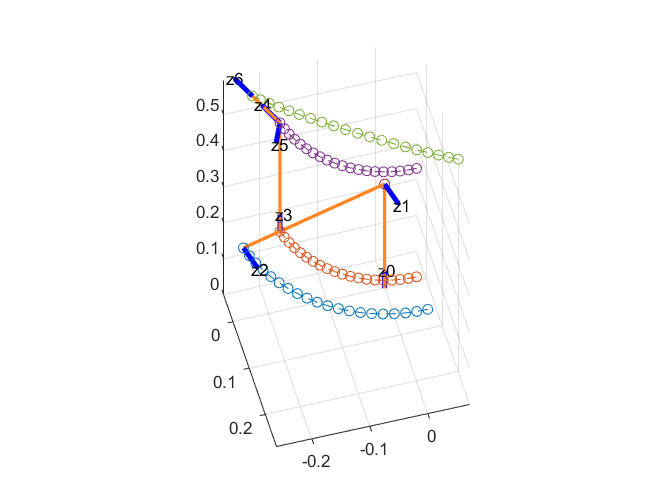

    w01=-4;
    w12=0;
    w23=0;
    w34=10;
    w45=10;
    w56=10;
    theta1 = theta1+w01;
    theta2 = theta2+w12;
    theta3 = theta3+w23;
    theta4 = theta4+w34;
    theta5 = theta5+w45;
    theta6 = theta6+w56;
    drawnow
end

fprintf("Final Position: ")

Final Position: 

fprintf("   6.:")

   6.:

fprintf('       -%s: (%s, %s, %s) \n', [["x";"y";"z"],A06(1:3,1:3)].')

       -x: (0.40056, -0.070629, -0.91355) 
       -y: (-0.89967, 0.15864, -0.40674) 
       -z: (0.17365, 0.98481, 0) 


fprintf("Angles: ")

Angles: 

fprintf('       -θ1: %.2f',theta1)

       -θ1: -80.00

fprintf('       -θ2: %.2f',theta2)

       -θ2: 0.00

fprintf('       -θ3: %.2f',theta3)

       -θ3: 0.00

fprintf('       -θ4: %.2f',theta4)

       -θ4: 200.00

fprintf('       -θ5: %.2f',theta5)

       -θ5: 200.00

fprintf('       -θ6: %.2f',theta6)

       -θ6: 200.00